# BME 2740 Interactive Lecture 15

# By: Dr . Asad Mirza

# Adapted From: Dr. Ilmar Tamames

#### Forward/Backward/Explicit Euler vs ODE Solvers

Euler methods are basic numerical techniques you can implement yourself, while MATLAB ODE solvers use more advanced numerical methods to obtain accurate solutions efficiently.

## Main Differences

#### Example 1 revisited

For 

 
$$\frac{\textrm{ds}}{\textrm{dt}}=e^t \left(8\;\cos \left(8t\right)+\sin \left(8t\right)\right),\ \ s\left(5\right)=0$$


Write the MATLAB code ODE Solver to approximate y(7), from 5 to 8.

clear;
% Set up variables
tspan = [5 8];
y0 = 0;
% Set up function
f = @(t, s) exp(t) .* (8 * cos(8 * t)) + sin(8 * t);
% Set up solver
[t_result, solution] = ode45(f, tspan, y0);
% Plot results
figure
plot(t_result, solution, '--b', 'LineWidth', 1.5); % Numerical solution
hold on;

MATLAB's Symbolic Toolbox let's you solve ODEs analytically. Make sure you have the toolbox installed in order to use it. You can type $\textrm{ver}$ into the Command Window to see a list of installed toolboxes.

% Analytical solution
syms s(t)
eqn = diff(s, t) == exp(t) * (8 * cos(8 * t) + sin(8 * t))

$$eqn(t) = \frac{\partial }{\partial t}s\left(t\right)={\mathrm{e}}^{t}\,\left(8\,\cos\left(8\,t\right)+\sin\left(8\,t\right)\right)$$

cond = s(5) == 0

$$cond = s\left(5\right)=0$$

sSol(t) = dsolve(eqn, cond)

$$sSol(t) = \sin\left(8\,t\right)\,{\mathrm{e}}^{t}-{\mathrm{e}}^{5}\,\sin\left(40\right)$$

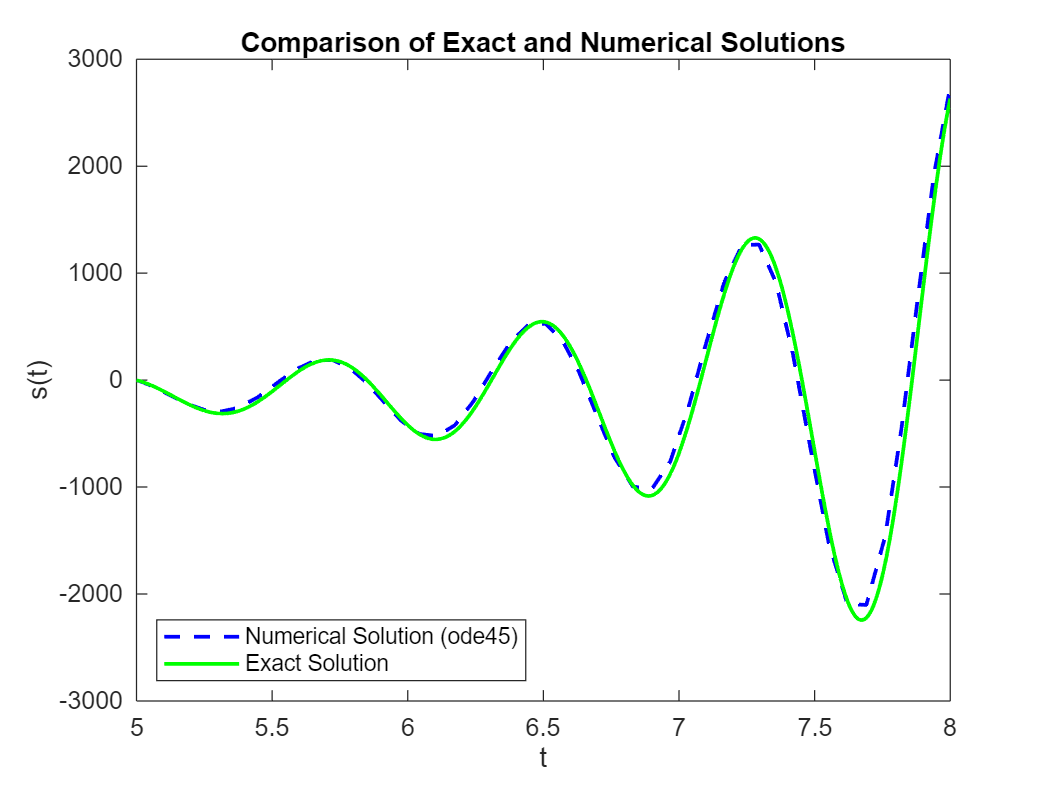

% Plot results
tt = linspace(5, 8, 1000); % More points for a smoother plot
plot(tt, sSol(tt), 'g', 'LineWidth', 1.5); % Exact solution
% Add legend and labels
legend('Numerical Solution (ode45)','Exact Solution',  'Location', 'southwest');
xlabel('t');
ylabel('s(t)');
title('Comparison of Exact and Numerical Solutions');

% Display the numerical solution at t = 7
numerical_at_7 = sSol(7);
fprintf('Numerical solution at t = 7 : %3.2f\n', double(numerical_at_7));

Numerical solution at t = 7 : -682.53


TIP: [dsolve](https://www.mathworks.com/help/symbolic/dsolve.html)

TIP: syms

## Scenario: Higher-Order Problems

As a teaching instructor for a biomechanics lab, you are helping students model how loads of biomechanically sensitive issues can be represented simply as a spring-mass system. From Newton’s laws, you know the mass times acceleration of the mass is equal to the balance of the forces exerted by the spring and gravity, expressed:


$$m\frac{dx^2 }{d^2 t}=mg-k\left(s+x\right)$$


For different sets of mass, spring stiffness, and initial displacements, we would like to simulate the evolution of the mass through time.

If we wanted to apply Forward Euler to this how could we?

#### Higher Order Derivatives

Euler’s method and by extension solvers appear unsuitable to handle differential equations containing degrees beyond the first derivative.


$$y_{k+1} =y_k +f{\left(t_k ,y_k \right)}h$$


We assume a constant first derivative when iterating for numerical integration.

#### Transformation to State System Form

A higher-order differential equation can be reformulated as a state system of just first derivatives.

Let's try it out with an example:


$$\frac{d^4 z}{dt^4 }+5\frac{d^3 z}{dt^3 }-2\frac{d^2 z}{dt^2 }-6\frac{dz}{dt}+3z=0$$


You need as many state variables as the highest derivative order.

Highest derivative is 4th order so we need at least 4 state variable


$$s=\left\lbrack \begin{array}{c}
z\\
z^{\prime } \\
{z^{\prime } }^{\prime } \\
{{z^{\prime } }^{\prime } }^{\prime } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
s_1 \\
s_2 \\
s_3 \\
s_4 
\end{array}\right\rbrack$$


For MATLAB we want to find $s^{\prime }$, the derivative of the state system


$$s^{\prime } =\left\lbrack \begin{array}{c}
z^{\prime } \\
{z^{\prime } }^{\prime } \\
{{z^{\prime } }^{\prime } }^{\prime } \\
{{{z^{\prime } }^{\prime } }^{\prime } }^{\prime } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
{s_1 }^{\prime } \\
{s_2 }^{\prime } \\
{s_3 }^{\prime } \\
{s_4 }^{\prime } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
s_2 \\
s_3 \\
s_4 \\
?
\end{array}\right\rbrack$$


We don't have a state system representation for ${{{z^{\prime } }^{\prime } }^{\prime } }^{\prime }$ but we do know what it is as part of our original system! And this original system can be rewritten as it's state variable equivalent.


$$\frac{d^4 z}{dt^4 }=-\left(5\frac{d^3 z}{dt^3 }-2\frac{d^2 z}{dt^2 }-6\frac{dz}{dt}+3z\right)$$



$${{{z^{\prime } }^{\prime } }^{\prime } }^{\prime } ={s_4 }^{\prime } =-\left(5s_4 -2s_{3\;} -6s_{2\;} +3s_1 \right)$$



$$s^{\prime } =\left\lbrack \begin{array}{c}
{s_1 }^{\prime } \\
{s_2 }^{\prime } \\
{s_3 }^{\prime } \\
{s_4 }^{\prime } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
s_2 \\
s_3 \\
s_4 \\
-\left(5\frac{d^3 z}{dt^3 }-2\frac{d^2 z}{dt^2 }-6\frac{dz}{dt}+3z\right)\;
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
s_2 \\
s_3 \\
s_4 \\
-\left(5s_4 -2s_{3\;} -6s_{2\;} +3s_1 \right)\;
\end{array}\right\rbrack$$


We now have a coupled system of ODEs:


$$\frac{{\textrm{ds}}_1 }{\textrm{dt}}=s_2$$



$$\frac{{\textrm{ds}}_2 }{\textrm{dt}}=s_3$$



$$\frac{{\textrm{ds}}_3 }{\textrm{dt}}=s_4$$



$$\frac{{\textrm{ds}}_4 }{\textrm{dt}}=-\left(5s_4 -2s_{3\;} -6s_{2\;} +3s_1 \right)$$


#### Example 1

Write the MATLAB code to compute the given second-order differential equation below using a step size of $h=0\ldotp 01$, given that $\frac{\textrm{dq}\left(z=0\right)}{\textrm{dz}}=5$ and  $q\left(z=0\right)=1$.


$$\frac{d^2 q}{dz^2 }-3\frac{\textrm{dq}}{\textrm{dz}}+2q=e^{-4z}$$


Steps: 

First, transform the differential equation into a system of 1st order differential equations by finding the state system:

Find how many state variables you need and take the derivative of the state system


$$\begin{array}{l}
s=\left\lbrack \begin{array}{c}
q\\
\frac{\textrm{dq}}{\textrm{dz}}
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
s_1 \\
s_2 
\end{array}\right\rbrack \\
s^{\prime } =\left\lbrack \begin{array}{c}
{s_1 }^{\prime } \\
{s_2 }^{\prime } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\frac{\textrm{dq}}{\textrm{dz}}\\
\frac{d^2 q}{dz^2 }
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
s_2 \\
?
\end{array}\right\rbrack 
\end{array}$$


Find what $\frac{d^2 q}{dz^2 }$ is in terms of original state variables


$$\frac{d^2 q}{dz^2 }=3\frac{\textrm{dq}}{\textrm{dz}}-2q+e^{-4z}$$



$${s_2 }^{\prime } =3s_2 -2s_1 +e^{-4z}$$



$$s^{\prime } =\left\lbrack \begin{array}{c}
{s_1 }^{\prime } \\
{s_2 }^{\prime } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
s_2 \\
3s_2 -2s_1 +e^{-4z} 
\end{array}\right\rbrack$$


We now have the state system that we can use in MATLAB


$$\frac{ds_1 }{dz}=s_2$$



$$\frac{ds_2 }{dz}=3s_2 -2s_1 +e^{-4z}$$


First let's look how we can use our old Euler method for it:

clear,clc,close all
% Step size for numerical integration
h = 0.001;
z = 0:h:1; % Time vector from 0 to 1 with step size h

% Initialize the solution matrix Y with two columns: [y1, y2]
S = zeros(2,length(z));

% Initial conditions: y1(0) = 1, y2(0) = 5 (derivative at t=0)
S(1:2, 1) = [1; 5]

S =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     5     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



% Define the function f as a handle returning the derivatives
f = @(z, s) [s(2), ...                 % ds1/dt = s2
             3*s(2) - 2*s(1) + exp(-4*z)] % ds2/dt = 3*s2 - 2*s1 + exp(-4*t)

f = function_handle with value:
    @(z,s)[s(2),3*s(2)-2*s(1)+exp(-4*z)]



% Euler method loop for numerical integration
for k = 1:length(z)-1
    S(:, k+1) = S(:, k) + h * f(z(k), S(:, k))'; % Use z(k) for time in function call
end

If you have the [Symbolic Math Toolbox](https://www.mathworks.com/products/symbolic.html) installed you can leverage it to directly solve most kinds of ODEs.

You can define a symbolic variable using [syms](https://www.mathworks.com/help/symbolic/syms.html) then use it with symbolic functions to define [symbolic equations](https://www.mathworks.com/help/symbolic/sym.eq.html?s_tid=doc_ta).

Best way to explain it is just to show you an example below for $\frac{d^2 q}{dz^2 }-3\frac{\textrm{dq}}{\textrm{dz}}+2q=e^{-4z}$,$\frac{\textrm{dq}\left(z=0\right)}{\textrm{dz}}=5$, and  $q\left(z=0\right)=1$. Notice, we don't need to worry about the state system here.

% Analytical solution using symbolic math
syms q(za);
% Define the first derivative of q
Dq = diff(q, za)

$$Dq(za) = \frac{\partial }{\partial \mathrm{za}}q\left(\mathrm{za}\right)$$

% Setup your diff eq
eqn = diff(q, za, 2) == 3*Dq - 2*q + exp(-4*za)

$$eqn(za) = \frac{\partial^{2}}{\partial {\mathrm{za}}^{2}}q\left(\mathrm{za}\right)=3\,\frac{\partial }{\partial \mathrm{za}}q\left(\mathrm{za}\right)+{\mathrm{e}}^{-4\,\mathrm{za}}-2\,q\left(\mathrm{za}\right)$$

% Initial conditions
cond = [q(0) == 1, Dq(0) == 5];
% Solve diff eq
qSol(za) = dsolve(eqn, cond)

$$qSol(za) = \frac{25\,{\mathrm{e}}^{2\,\mathrm{za}}}{6}+\frac{{\mathrm{e}}^{-4\,\mathrm{za}}}{30}-\frac{16\,{\mathrm{e}}^{\mathrm{za}}}{5}$$

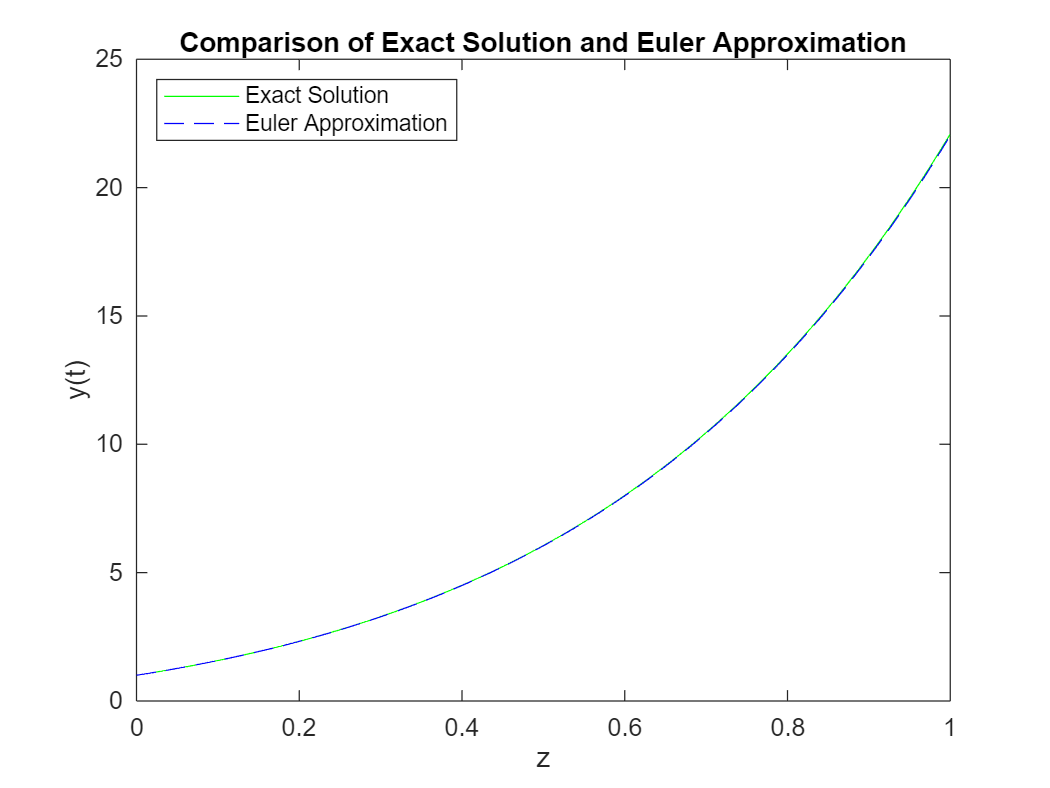

% Plotting the solutions
zz = linspace(0, 1, 1000); % Time vector for smooth plot of exact solution
figure;
% Our solution qSol is a function that takes in an input so we can use it
% like one
plot(zz, qSol(zz), 'g');
hold on;
plot(z, S(1,:), '--b'); % Plot numerical solution
hold off;
% Add legend and labels for better visualization
legend('Exact Solution','Euler Approximation', 'Location', 'northwest');
xlabel('z');
ylabel('y(t)');
title('Comparison of Exact Solution and Euler Approximation');

Now let's try with ode45:

% Set up variables for numerical ODE solver
zspan = [0 1]; % Time range for the solution
q0 = [1; 5]; % Initial conditions: q(0) = 1, dq/dz(0) = 5
% Define the system of ODEs as a function handle
f = @(z, s) [s(2); ... % ds1/dt = s2
             3*s(2) - 2*s(1) + exp(-4*z)] % ds2/dt = 3*s2 - 2*s1 + exp(-4*z)

f = function_handle with value:
    @(z,s)[s(2);3*s(2)-2*s(1)+exp(-4*z)]


% Solve the ODE using ode45
[zout, sout] = ode45(f, zspan, q0)

zout =          0
    0.0100
    0.0201
    0.0301
    0.0402
    0.0652
    0.0902
    0.1152
    0.1402
    0.1652


sout =     1.0000    5.0000
    1.0509    5.1421
    1.1033    5.2871
    1.1572    5.4350
    1.2126    5.5861
    1.3570    5.9756
    1.5115    6.3856
    1.6765    6.8175
    1.8526    7.2726
    2.0403    7.7522


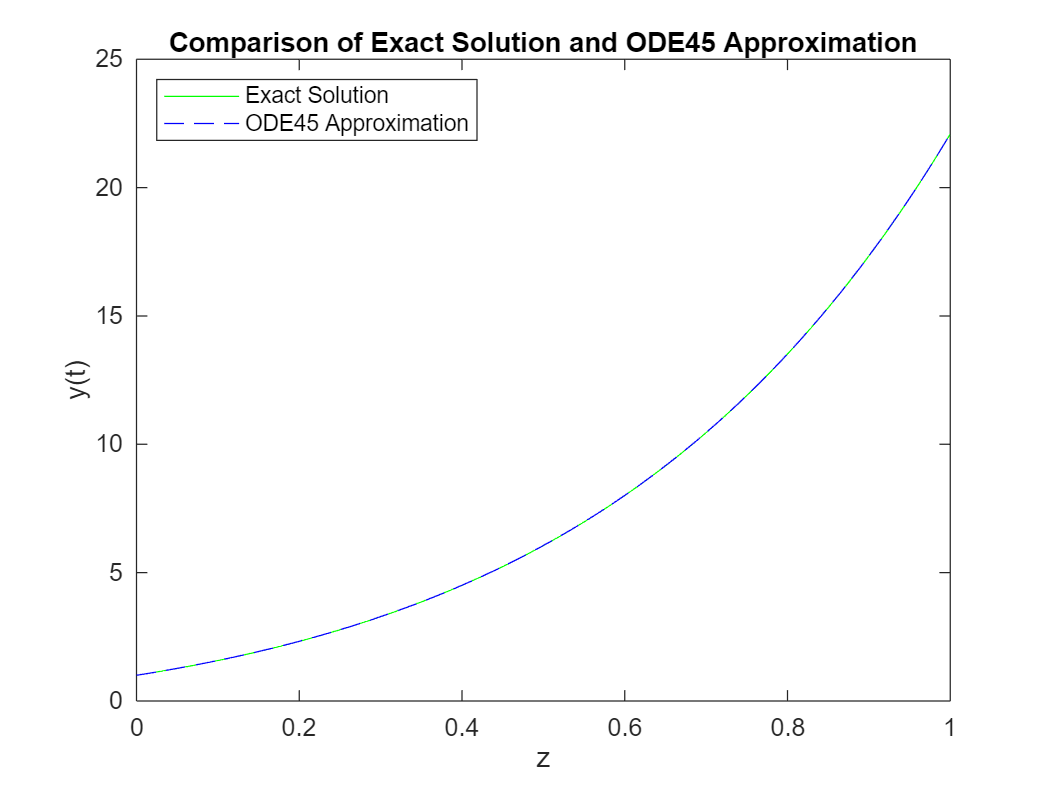

% Plotting
figure
plot(zz, qSol(zz), 'g');
hold on;
plot(zout, sout(:,1), '--b'); % Plot numerical solution
hold off;
% Add legend and labels for better visualization
legend('Exact Solution','ODE45 Approximation', 'Location', 'northwest');
xlabel('z');
ylabel('y(t)');
title('Comparison of Exact Solution and ODE45 Approximation');

Check the absolute error between Forward Euler and the ODE45 Solver.

[length(zout) length(z)]

ans =           45        1001


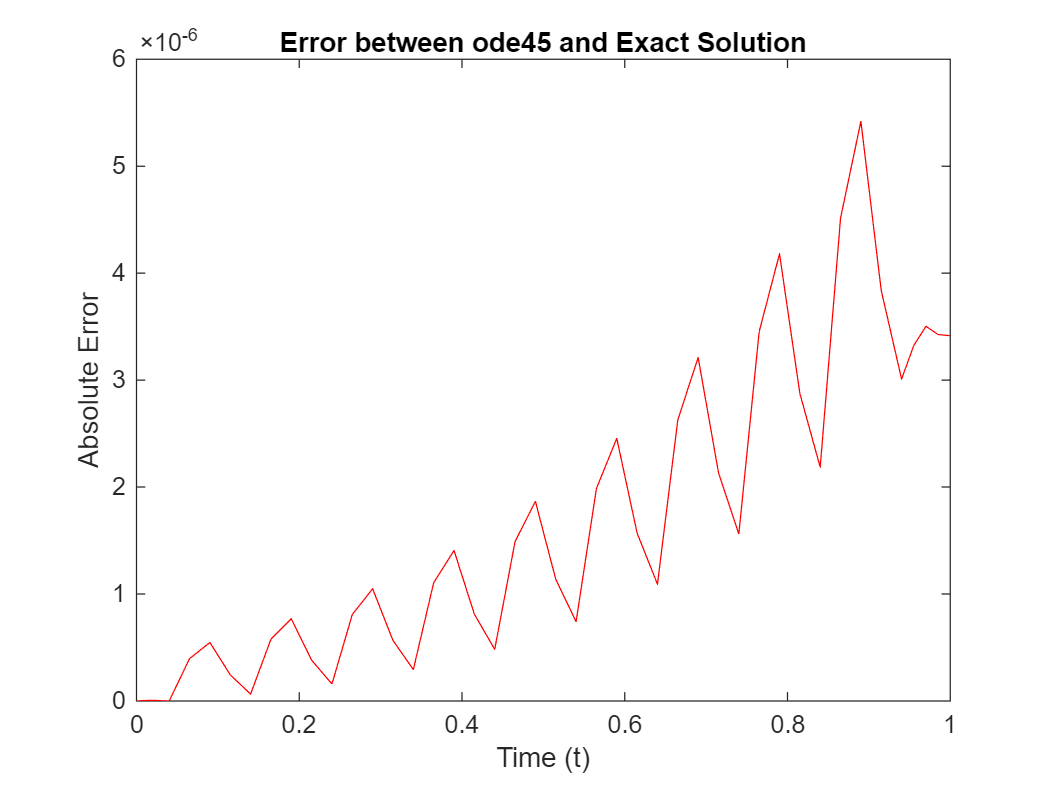

error = abs(sout(:, 1) - qSol(zout));
figure;
plot(zout, error, 'r');
xlabel('Time (t)');
ylabel('Absolute Error');
title('Error between ode45 and Exact Solution');

#### Example 2:

 We consider a simple RLC circuit in series that is modeled by the differential equation:

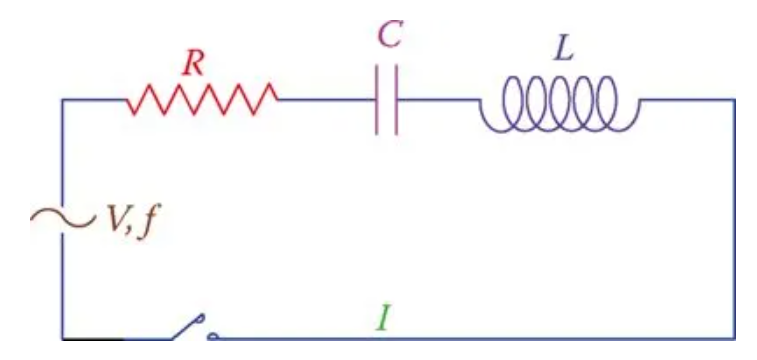


$$\frac{d^2 i}{dt^2 }+2\alpha \frac{\textrm{di}}{\textrm{dt}}+\omega^2 i\left(t\right)=0$$


where i(t) represents the current traveling through the circuit as a function of time, t. The coefficients α and ω incorporate the constants used in a resistor, inductor, and capacitor. 

a) For α = .4 and ω = 1, compute the second-order differential equation and plot it for 16 seconds given that$\frac{\textrm{di}\left(0\right)}{\textrm{dt}}=0$ and  $i\left(0\right)=-1$.

First transform the differential equation into a system of 1st order differential equations using its state system form. 


$$\begin{array}{l}
s=\left\lbrack \begin{array}{c}
i\\
\frac{\textrm{di}}{\textrm{dt}}
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
s_1 \\
s_2 
\end{array}\right\rbrack \\
s^{\prime } =\left\lbrack \begin{array}{c}
{s_1 }^{\prime } \\
{s_2 }^{\prime } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\frac{\textrm{di}}{\textrm{dt}}\\
\frac{d^2 i}{dt^2 }
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
s_2 \\
?
\end{array}\right\rbrack 
\end{array}$$


Find what $\frac{d^2 i}{dt^2 }$ is in terms of original state variables


$$\frac{d^2 i}{dt^2 }+2\alpha \frac{\textrm{di}}{\textrm{dt}}+\omega^2 i\left(t\right)=0$$



$${s_2 }^{\prime } =-2{\alpha \;s}_2 -\omega {\;}^2 s_1$$



$$s^{\prime } =\left\lbrack \begin{array}{c}
{s_1 }^{\prime } \\
{s_2 }^{\prime } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
s_2 \\
-2\alpha \;s_2 -\omega {\;}^2 s_1 
\end{array}\right\rbrack$$


We now have the state system that MATLAB wants:


$$\frac{{\textrm{ds}}_1 }{\textrm{dt}}=s_2$$



$$\frac{{\textrm{ds}}_2 }{\textrm{dt}}=-2\alpha \;s_2 -\omega {\;}^2 s_1$$


Bonus: Find when $i\left(t\right)\ge -0\ldotp 2$ for the first time.

% State system form of the second-order ODE:
% ds1 = s(2) (first derivative of current)
% ds2 = -2*a*s(2) - (w^2)*s(1) (second derivative)

% Set up variables
tspan = [0 16]; % Time range for the solution
y0 = [-1; 0]; % Initial conditions: i(0) = -1, di/dt(0) = 0
w = sqrt(2); % Natural frequency (can be modified as needed)
a = 0.7; % Damping factor (can be modified for graphical observations)

% Define the system of ODEs as a function handle
f = @(t, s) [s(2); ... % ds1/dt = s2
             -2*a*s(2) - (w^2)*s(1)] % ds2/dt = -2*a*s(2) - (w^2)*s(1)

f = function_handle with value:
    @(t,s)[s(2);-2*a*s(2)-(w^2)*s(1)]



% Solve the ODE using ode45
[zout, sout] = ode45(f, tspan, y0)

zout =          0
    0.0000
    0.0001
    0.0001
    0.0001
    0.0002
    0.0004
    0.0005
    0.0006
    0.0012


sout =    -1.0000         0
   -1.0000    0.0001
   -1.0000    0.0001
   -1.0000    0.0002
   -1.0000    0.0002
   -1.0000    0.0005
   -1.0000    0.0007
   -1.0000    0.0010
   -1.0000    0.0012
   -1.0000    0.0025



% Analytical solution using symbolic math
syms q(ta);
eqn = diff(q, ta, 2) == -2*a*diff(q, ta) - (w^2)*q

$$eqn(ta) = \frac{\partial^{2}}{\partial {\mathrm{ta}}^{2}}q\left(\mathrm{ta}\right)=-\frac{7\,\frac{\partial }{\partial \mathrm{ta}}q\left(\mathrm{ta}\right)}{5}-2\,q\left(\mathrm{ta}\right)$$

DQ = diff(q, ta)

$$DQ(ta) = \frac{\partial }{\partial \mathrm{ta}}q\left(\mathrm{ta}\right)$$

cond = [q(0) == -1, DQ(0) == 0] % Initial conditions

$$cond = \left(\begin{array}{cc} q\left(0\right)=-1 & \left({\left(\frac{\partial }{\partial \mathrm{ta}}q\left(\mathrm{ta}\right)\right)|}_{\mathrm{ta}=0}\right)=0 \end{array}\right)$$

qSol(ta) = dsolve(eqn, cond)

$$qSol(ta) = -\frac{{\mathrm{e}}^{-\frac{7\,\mathrm{ta}}{10}}\,\left(151\,\cos\left(\frac{\sqrt{151}\,\mathrm{ta}}{10}\right)+7\,\sqrt{151}\,\sin\left(\frac{\sqrt{151}\,\mathrm{ta}}{10}\right)\right)}{151}$$

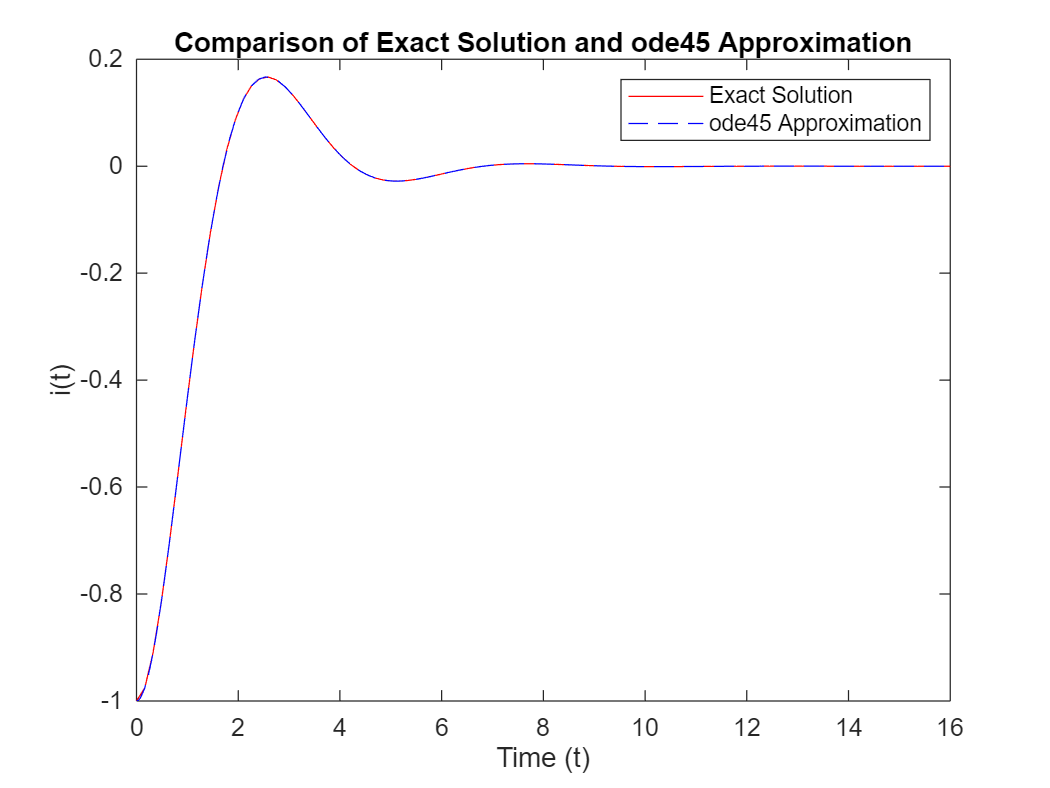


% Plot the analytical and numerical solutions
figure;
tt = linspace(0, 16, 100); % Time vector for smooth plot of exact solution
plot(tt, qSol(tt), 'r', 'DisplayName', 'Exact Solution');
hold on;
plot(zout, sout(:, 1), '--b', 'DisplayName', 'ode45 Approximation');
hold off;

% Add legend and labels for better visualization
legend('show', 'Location', 'northeast');
xlabel('Time (t)');
ylabel('i(t)');
title('Comparison of Exact Solution and ode45 Approximation');

% Bonus: Find the first time when i(t) >= -0.2
ind = find(sout(:, 1) >= -0.2, 1); % Find the first index where i(t) >= -0.2
if ~isempty(ind)
    fprintf('The first time when i(t) >= -0.2 is at t = %.4f\n', zout(ind));
else
    fprintf('Condition i(t) >= -0.2 was not met within the given time span.\n');
end

The first time when i(t) >= -0.2 is at t = 1.4142


#### Example 3:

Write the MATLAB code to compute the given second-order differential equation, given that $\frac{\textrm{dx}\left(0\right)}{\textrm{dt}}=2\ldotp 5$ and  $q\left(0\right)=-1$ from 0 to 4.


$$4\frac{d^2 x}{dt^2 }+20\frac{\textrm{dx}}{\textrm{dt}}+16x=0$$


First transform the differential equation into a system of 1st order differential equations using its state system form. 


$$\begin{array}{l}
s=\left\lbrack \begin{array}{c}
x\\
\frac{\textrm{dx}}{\textrm{dt}}
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
s_1 \\
s_2 
\end{array}\right\rbrack \\
s^{\prime } =\left\lbrack \begin{array}{c}
{s_1 }^{\prime } \\
{s_2 }^{\prime } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\frac{\textrm{dx}}{\textrm{dt}}\\
\frac{d^2 x}{dt^2 }
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
s_2 \\
?
\end{array}\right\rbrack 
\end{array}$$


Find what $\frac{d^2 x}{dt^2 }$ is in terms of original state variables


$$4\frac{d^2 x}{dt^2 }+20\frac{\textrm{dx}}{\textrm{dt}}+16x=0$$



$${s_2 }^{\prime } =-5s_2 -4s_1$$



$$s^{\prime } =\left\lbrack \begin{array}{c}
{s_1 }^{\prime } \\
{s_2 }^{\prime } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
s_2 \\
-5s_2 -4s_1 
\end{array}\right\rbrack$$


We now have the state system that MATLAB wants:


$$\frac{{\textrm{ds}}_1 }{\textrm{dt}}=s_2$$



$$\frac{{\textrm{ds}}_2 }{\textrm{dt}}={-5s}_2 -4s_1$$


% State System form of the second-order ODE:
% ds1 = s(2) (first derivative of x)
% ds2 = -5*s(2) - 4*s(1) (second derivative of x)

% Set up variables
tspan = [0 4]; % Time range for the solution
x0 = [-1; 2.5]; % Initial conditions: x(0) = -1, dx/dt(0) = 2.5

% Define the system of ODEs as a function handle
f = @(t, s) [s(2); ... % ds1/dt = s(2)
             -5*s(2) - 4*s(1)] % ds2/dt = -5*s(2) - 4*s(1)

f = function_handle with value:
    @(t,s)[s(2);-5*s(2)-4*s(1)]



% Solve the ODE using ode45
[tout, sout] = ode45(f, tspan, x0)

tout =          0
    0.0148
    0.0296
    0.0443
    0.0591
    0.1126
    0.1662
    0.2197
    0.2733
    0.3248


sout =    -1.0000    2.5000
   -0.9640    2.3779
   -0.9297    2.2625
   -0.8971    2.1534
   -0.8660    2.0502
   -0.7652    1.7208
   -0.6805    1.4515
   -0.6089    1.2316
   -0.5481    1.0511
   -0.4977    0.9069



% Analytical solution using symbolic math
syms x(ta);
DQ = diff(x, ta)

$$DQ(ta) = \frac{\partial }{\partial \mathrm{ta}}x\left(\mathrm{ta}\right)$$

eqn = diff(x, ta, 2) == -5*DQ - 4*x

$$eqn(ta) = \frac{\partial^{2}}{\partial {\mathrm{ta}}^{2}}x\left(\mathrm{ta}\right)=-5\,\frac{\partial }{\partial \mathrm{ta}}x\left(\mathrm{ta}\right)-4\,x\left(\mathrm{ta}\right)$$

cond = [x(0) == -1, DQ(0) == 2.5] % Initial conditions

$$cond = \left(\begin{array}{cc} x\left(0\right)=-1 & \left({\left(\frac{\partial }{\partial \mathrm{ta}}x\left(\mathrm{ta}\right)\right)|}_{\mathrm{ta}=0}\right)=\frac{5}{2} \end{array}\right)$$

xSol(ta) = dsolve(eqn, cond)

$$xSol(ta) = -\frac{{\mathrm{e}}^{-\mathrm{ta}}}{2}-\frac{{\mathrm{e}}^{-4\,\mathrm{ta}}}{2}$$

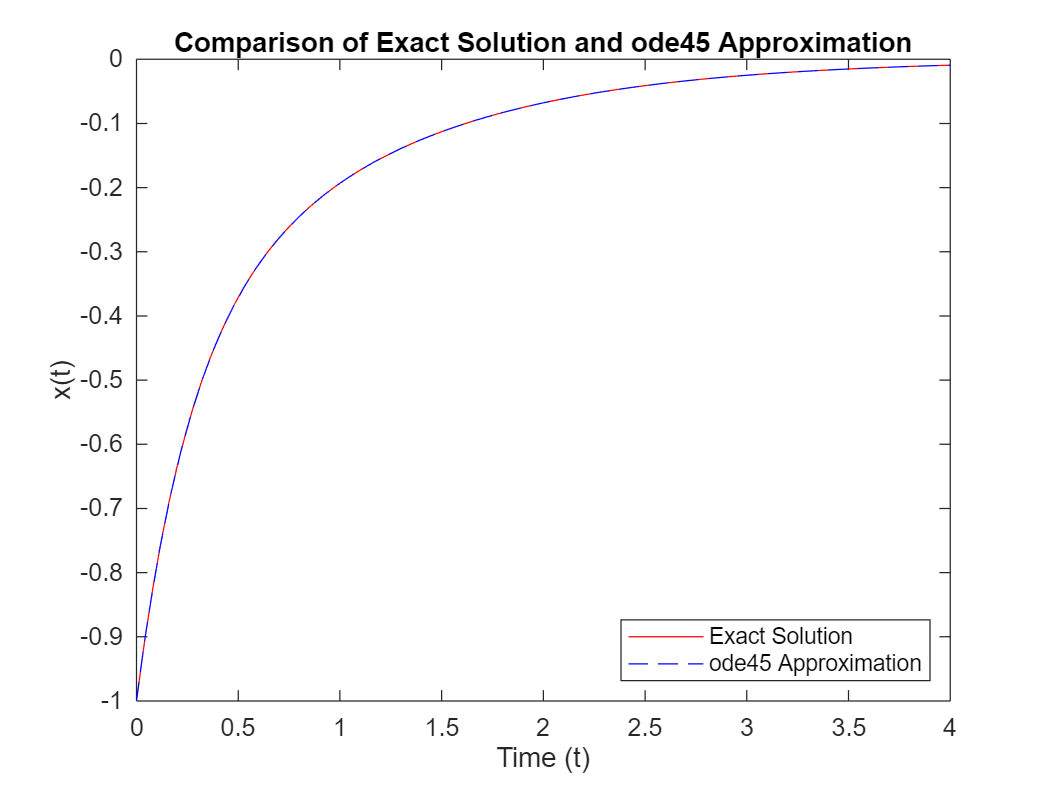

% Plot the analytical and numerical solutions
figure;
tt = linspace(0, 4, 100); % Time vector for smooth plot of exact solution
plot(tt, xSol(tt), 'r');
hold on;
plot(tout, sout(:, 1), '--b');
hold off;
% Add legend and labels for better visualization
legend('Exact Solution','ode45 Approximation', 'Location', 'southeast');
xlabel('Time (t)');
ylabel('x(t)');
title('Comparison of Exact Solution and ode45 Approximation');